a = 1 + mod(109,3)

a = 2

Problem1


t = linspace(-1,1)

t =    -1.0000   -0.9798   -0.9596   -0.9394   -0.9192   -0.8990   -0.8788   -0.8586   -0.8384   -0.8182   -0.7980   -0.7778   -0.7576   -0.7374   -0.7172   -0.6970   -0.6768   -0.6566   -0.6364   -0.6162   -0.5960   -0.5758   -0.5556   -0.5354   -0.5152   -0.4949   -0.4747   -0.4545   -0.4343   -0.4141   -0.3939   -0.3737   -0.3535   -0.3333   -0.3131   -0.2929   -0.2727   -0.2525   -0.2323   -0.2121   -0.1919   -0.1717   -0.1515   -0.1313   -0.1111   -0.0909   -0.0707   -0.0505   -0.0303   -0.0101


y1 = cos(2*pi*a*t) %1

y1 =     1.0000    0.9679    0.8738    0.7237    0.5272    0.2969    0.0476   -0.2048   -0.4441   -0.6549   -0.8237   -0.9397   -0.9955   -0.9874   -0.9161   -0.7861   -0.6056   -0.3863   -0.1423    0.1108    0.3569    0.5801    0.7660    0.9029    0.9819    0.9980    0.9501    0.8413    0.6785    0.4723    0.2358   -0.0159   -0.2665   -0.5000   -0.7015   -0.8580   -0.9595   -0.9995   -0.9754   -0.8888   -0.7453   -0.5539   -0.3271   -0.0792    0.1736    0.4154    0.6306    0.8053    0.9284    0.9920


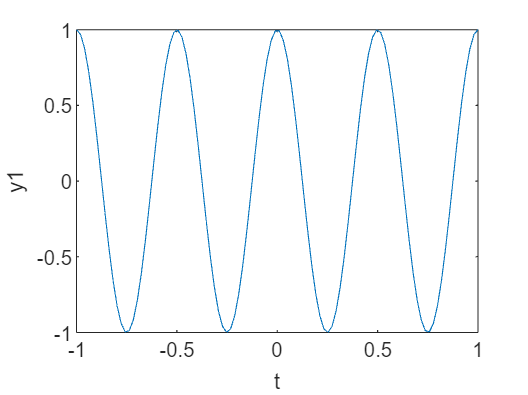

plot(t,y1)
xlabel("t"); ylabel("y1")


y2 = cos(5*pi*a*t + pi/4) %2

y2 =     0.7071    0.1502   -0.4653   -0.8995   -0.9834   -0.6843   -0.1187    0.4931    0.9129    0.9771    0.6608    0.0872   -0.5205   -0.9254   -0.9699   -0.6367   -0.0555    0.5473    0.9369    0.9617    0.6119    0.0238   -0.5736   -0.9476   -0.9525   -0.5865    0.0079    0.5993    0.9572    0.9424    0.5605   -0.0397   -0.6244   -0.9659   -0.9313   -0.5339    0.0713    0.6488    0.9737    0.9193    0.5069   -0.1030   -0.6727   -0.9804   -0.9063   -0.4792    0.1345    0.6958    0.9862    0.8924


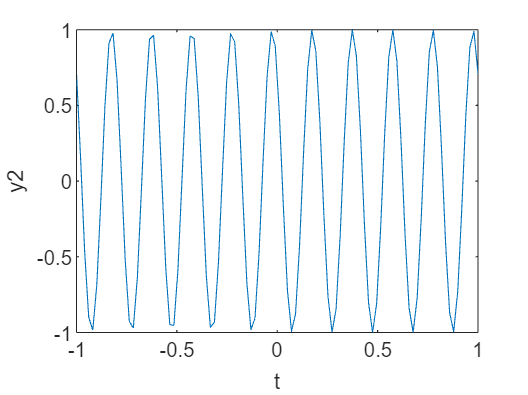

plot(t,y2)
xlabel("t"); ylabel("y2")


y3 = exp(-2*a*t) %3

y3 =    54.5982   50.3597   46.4503   42.8444   39.5185   36.4507   33.6210   31.0110   28.6037   26.3832   24.3351   22.4460   20.7035   19.0963   17.6139   16.2465   14.9853   13.8220   12.7490   11.7593   10.8465   10.0045    9.2278    8.5115    7.8507    7.2413    6.6791    6.1606    5.6824    5.2413    4.8344    4.4591    4.1130    3.7937    3.4992    3.2275    2.9770    2.7459    2.5327    2.3361    2.1548    1.9875    1.8332    1.6909    1.5596    1.4386    1.3269    1.2239    1.1289    1.0412


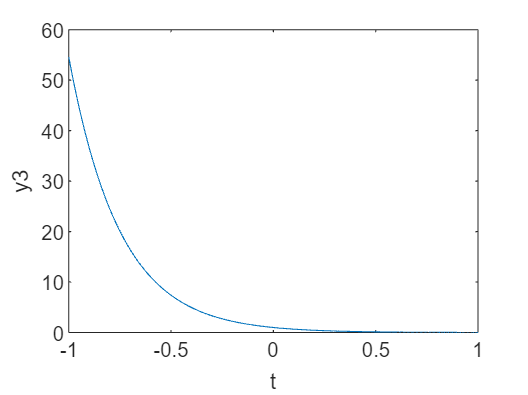

plot(t,y3)
xlabel("t"); ylabel("y3")


y4 = exp(-0.25*a*t).*sin(20*pi*t)

y4 =     0.0000    1.5585    0.9162   -0.9888   -1.4792    0.0994    1.5080    0.7891   -1.0140   -1.3694    0.1887    1.4529    0.6692   -1.0304   -1.2616    0.2682    1.3940    0.5567   -1.0389   -1.1563    0.3383    1.3321    0.4515   -1.0400   -1.0539    0.3996    1.2678    0.3536   -1.0345   -0.9547    0.4526    1.2017    0.2629   -1.0231   -0.8591    0.4976    1.1344    0.1793   -1.0064   -0.7673    0.5352    1.0666    0.1025   -0.9849   -0.6795    0.5658    0.9985    0.0325   -0.9594   -0.5959


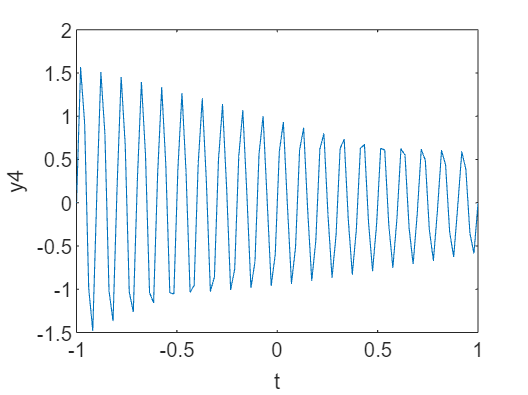

plot(t,y4)
xlabel("t"); ylabel("y4")

question2

t = linspace(-5,5)

t =    -5.0000   -4.8990   -4.7980   -4.6970   -4.5960   -4.4949   -4.3939   -4.2929   -4.1919   -4.0909   -3.9899   -3.8889   -3.7879   -3.6869   -3.5859   -3.4848   -3.3838   -3.2828   -3.1818   -3.0808   -2.9798   -2.8788   -2.7778   -2.6768   -2.5758   -2.4747   -2.3737   -2.2727   -2.1717   -2.0707   -1.9697   -1.8687   -1.7677   -1.6667   -1.5657   -1.4646   -1.3636   -1.2626   -1.1616   -1.0606   -0.9596   -0.8586   -0.7576   -0.6566   -0.5556   -0.4545   -0.3535   -0.2525   -0.1515   -0.0505


z = inline("exp(-t/2)","t")

z =

     Inline function:
     z(t) = exp(-t/2)



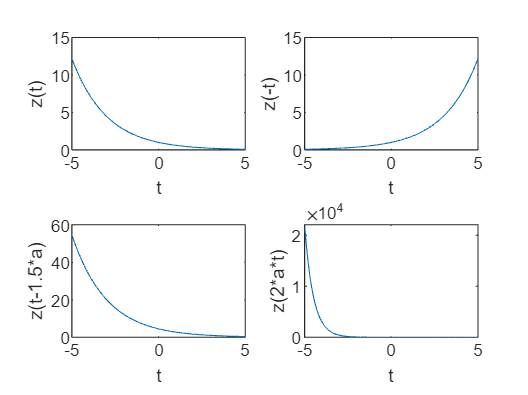

subplot(2,2,1)
plot(t,z(t));xlabel("t"); ylabel("z(t)")
subplot(2,2,2)
plot(t,z(-t));xlabel("t"); ylabel("z(-t)")
subplot(2,2,3)
plot(t,z(t-1.5*a));xlabel("t"); ylabel("z(t-1.5*a)")
subplot(2,2,4)
plot(t,z(2*a*t));xlabel("t"); ylabel("z(2*a*t)")

question3

load ECG_Data.txt
z = ECG_Data

z =     0.2284
    0.2240
    0.2206
    0.2163
    0.2111
    0.2059
    0.1998
    0.1964
    0.1938
    0.1886


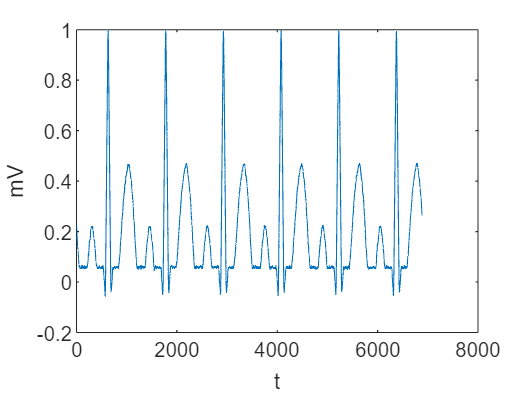

figure; plot(z) ;xlabel("t"); ylabel("mV")


load RainFallIndia_Jan.txt
load RainFallIndia_July.txt
w = RainFallIndia_Jan

w =   107.3000
   43.7000
   32.7000
   42.2000
   33.3000
   28.0000
   42.2000
   42.2000
   83.7000
   70.3000


v = RainFallIndia_July

v = 1.0e+03 *

    0.2850
    0.4213
    0.4654
    0.6601
    0.9909
    0.2174
    0.8519
    0.6601
    0.2720
    0.4608


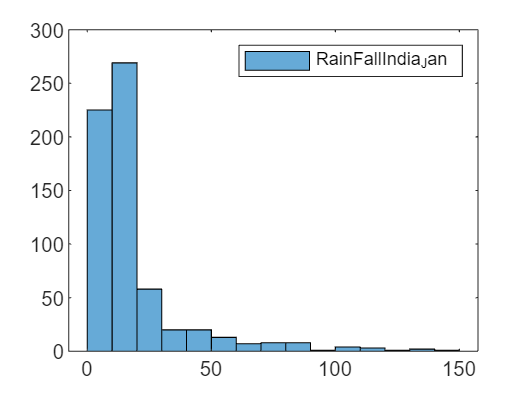

figure; histogram(w);legend("RainFallIndia_Jan")

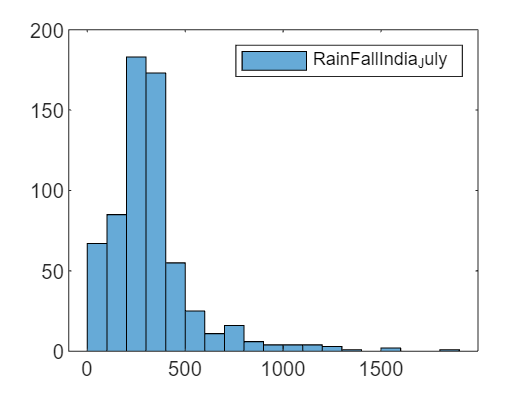

figure; histogram(v);legend("RainFallIndia_July")


Jan_mean = mean(w)

Jan_mean = 18.3513

Jan_std = std(w)

Jan_std = 21.0991

July_mean = mean(v)

July_mean = 326.0936

July_std = std(v)

July_std = 221.5326

question 4


[y,Fs] = audioread("speech.wav")

y =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Fs = 16000

sound(y,Fs)
z=size(y)

z =        19120           1


F = 250*a

F = 500

Y = y *cos(2*pi*F/Fs)

Y =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


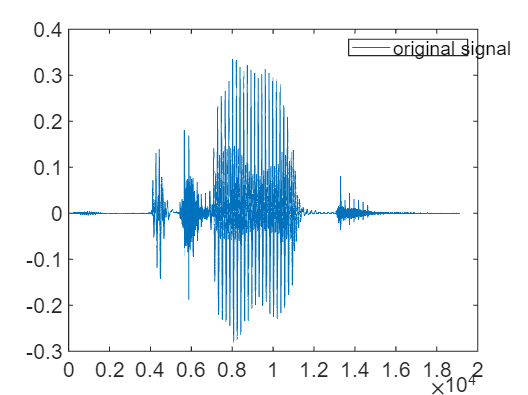

sound(y,Fs)
figure; plot(y) ;legend("original signal")

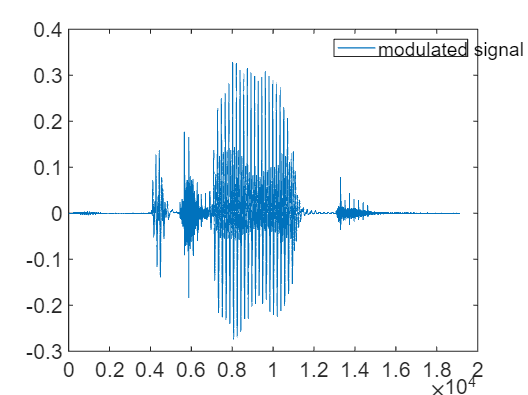

figure; plot(Y); legend("modulated signal")

Fy = fft(y) 

Fy = 1.0e+02 *

   0.3704 + 0.0000i
  -0.2912 - 0.0933i
   0.1662 + 0.0740i
  -0.1196 - 0.0416i
   0.0800 + 0.0614i
   0.0022 - 0.0479i
  -0.0223 - 0.0201i
  -0.0280 + 0.0329i
   0.0421 + 0.0178i
  -0.0045 - 0.0350i


FY = fft(Y)

FY = 1.0e+02 *

   0.3632 + 0.0000i
  -0.2856 - 0.0915i
   0.1630 + 0.0725i
  -0.1173 - 0.0408i
   0.0785 + 0.0602i
   0.0022 - 0.0470i
  -0.0219 - 0.0197i
  -0.0275 + 0.0323i
   0.0413 + 0.0175i
  -0.0044 - 0.0344i


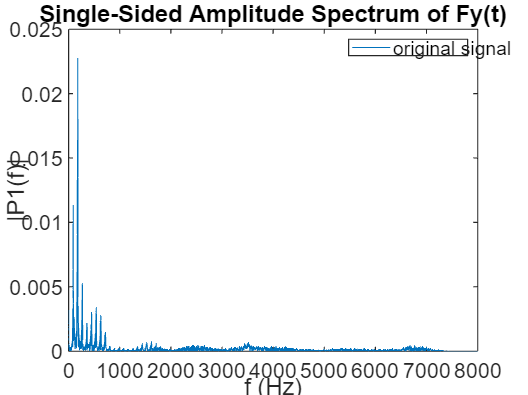

 %plotting fft of original                           
T = 1/Fs;             % Sampling period       
L = z(1);             % Length of signal
t = (0:L-1)*T;    % Time vector
P2 = abs(Fy/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f,P1) 
title("Single-Sided Amplitude Spectrum of Fy(t)")
legend("original signal")
xlabel("f (Hz)")
ylabel("|P1(f)|")

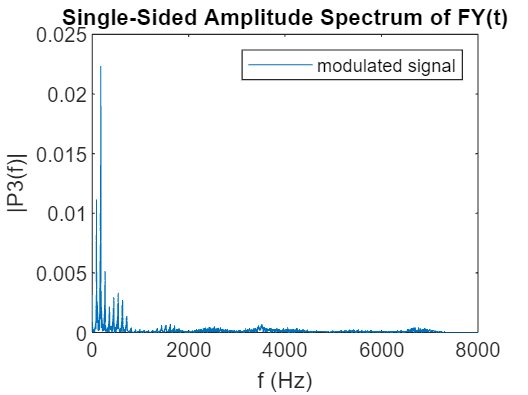

%plotting fft of modulated
T = 1/Fs;             % Sampling period       
L = z(1);             % Length of signal
t = (0:L-1)*T;    % Time vector
P4 = abs(FY/L);
P3 = P4(1:L/2+1);
P3(2:end-1) = 2*P3(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f,P3) 
title("Single-Sided Amplitude Spectrum of FY(t)")
legend("modulated signal")
xlabel("f (Hz)")
ylabel("|P3(f)|")

question5


T = 5000*0.001

T = 5

t = linspace(0,T,5000)

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


w1 = sin(200*a*t)

w1 =          0    0.3895    0.7175    0.9321    0.9996    0.9091    0.6751    0.3345   -0.0590   -0.4432   -0.7573   -0.9519   -0.9961   -0.8830   -0.6304   -0.2783    0.1178    0.4953    0.7945    0.9683    0.9891    0.8537    0.5835    0.2211   -0.1762   -0.5457   -0.8290   -0.9814   -0.9787   -0.8215   -0.5345   -0.1632    0.2340    0.5942    0.8606    0.9910    0.9649    0.7864    0.4837    0.1047   -0.2910   -0.6406   -0.8891   -0.9972   -0.9477   -0.7486   -0.4312   -0.0458    0.3469    0.6848


w2 = sin(220*a*t)

w2 =          0    0.4260    0.7709    0.9688    0.9821    0.8082    0.4804    0.0609   -0.3701   -0.7306   -0.9519   -0.9917   -0.8426   -0.5329   -0.1217    0.3128    0.6876    0.9314    0.9977    0.8739    0.5835    0.1819   -0.2543   -0.6421   -0.9075   -1.0000   -0.9019   -0.6319   -0.2415    0.1949    0.5942    0.8802    0.9985    0.9265    0.6780    0.3002   -0.1348   -0.5441   -0.8497   -0.9934   -0.9477   -0.7215   -0.3578    0.0742    0.4919    0.8160    0.9845    0.9654    0.7623    0.4140


Fs = 44100

Fs = 44100

w3 = [w1(1:2500) w2(2501:5000)]

w3 =          0    0.3895    0.7175    0.9321    0.9996    0.9091    0.6751    0.3345   -0.0590   -0.4432   -0.7573   -0.9519   -0.9961   -0.8830   -0.6304   -0.2783    0.1178    0.4953    0.7945    0.9683    0.9891    0.8537    0.5835    0.2211   -0.1762   -0.5457   -0.8290   -0.9814   -0.9787   -0.8215   -0.5345   -0.1632    0.2340    0.5942    0.8606    0.9910    0.9649    0.7864    0.4837    0.1047   -0.2910   -0.6406   -0.8891   -0.9972   -0.9477   -0.7486   -0.4312   -0.0458    0.3469    0.6848


audiowrite("sg1.wav",w3,Fs)
sound(w3,Fs)


question6


t = linspace(0,5,10000)

t =          0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145    0.0150    0.0155    0.0160    0.0165    0.0170    0.0175    0.0180    0.0185    0.0190    0.0195    0.0200    0.0205    0.0210    0.0215    0.0220    0.0225    0.0230    0.0235    0.0240    0.0245


f1 = sin(2*pi*220*t) %LA

f1 =          0    0.6375    0.9823    0.8762    0.3679   -0.3093   -0.8446   -0.9921   -0.6841   -0.0622    0.5883    0.9688    0.9045    0.4250   -0.2496   -0.8096   -0.9980   -0.7282   -0.1241    0.5369    0.9515    0.9292    0.4804   -0.1889   -0.7716   -1.0000   -0.7694   -0.1855    0.4834    0.9305    0.9504    0.5340   -0.1275   -0.7305   -0.9982   -0.8076   -0.2463    0.4281    0.9059    0.9679    0.5855   -0.0656   -0.6867   -0.9925   -0.8427   -0.3061    0.3711    0.8779    0.9817    0.6348


f2 = sin(2*pi*246.94*t) %SI

f2 =          0    0.7003    0.9998    0.7270    0.0381   -0.6726   -0.9984   -0.7527   -0.0762    0.6439    0.9955    0.7773    0.1142   -0.6142   -0.9911   -0.8007   -0.1520    0.5837    0.9853    0.8229    0.1896   -0.5523   -0.9781   -0.8440   -0.2269    0.5201    0.9694    0.8638    0.2638   -0.4872   -0.9594   -0.8824   -0.3004    0.4535    0.9479    0.8997    0.3366   -0.4192   -0.9351   -0.9157   -0.3722    0.3843    0.9209    0.9304    0.4074   -0.3488   -0.9053   -0.9437   -0.4419    0.3128


f3 = sin(2*pi*261.63*t) %DO

f3 =          0    0.7325    0.9973    0.6253   -0.1460   -0.8240   -0.9760   -0.5047    0.2888    0.8979    0.9337    0.3733   -0.4254   -0.9525   -0.8714   -0.2339    0.5530    0.9868    0.7905    0.0895   -0.6686   -0.9999   -0.6927    0.0568    0.7700    0.9916    0.5800   -0.2019   -0.8549   -0.9620   -0.4549    0.3427    0.9215    0.9119    0.3200   -0.4761   -0.9683   -0.8422   -0.1783    0.5994    0.9944    0.7545    0.0328   -0.7098   -0.9992   -0.6506    0.1134    0.8050    0.9826    0.5328


f4 = sin(2*pi*293.66 *t) %RA

f4 =          0    0.7972    0.9626    0.3650   -0.5218   -0.9951   -0.6796    0.1745    0.8903    0.9005    0.1970   -0.6627   -0.9971   -0.5412    0.3436    0.9561    0.8108    0.0229   -0.7832   -0.9685   -0.3862    0.5022    0.9926    0.6962   -0.1519   -0.8797   -0.9102   -0.2193    0.6454    0.9986    0.5603   -0.3220   -0.9492   -0.8240   -0.0457    0.7688    0.9739    0.4072   -0.4823   -0.9895   -0.7125    0.1293    0.8686    0.9194    0.2416   -0.6277   -0.9995   -0.5791    0.3003    0.9417


f5 = sin(2*pi*329.63 *t) %ME

f5 =          0    0.8602    0.8773    0.0346   -0.8421   -0.8934   -0.0691    0.8229    0.9084    0.1036   -0.8027   -0.9223   -0.1379    0.7816    0.9351    0.1721   -0.7596   -0.9468   -0.2061    0.7367    0.9574    0.2398   -0.7128   -0.9668   -0.2732    0.6881    0.9751    0.3063   -0.6626   -0.9822   -0.3391    0.6363    0.9881    0.3714   -0.6093   -0.9928   -0.4033    0.5815    0.9964    0.4347   -0.5530   -0.9987   -0.4656    0.5239    0.9999    0.4959   -0.4941   -0.9998   -0.5256    0.4637


f6 = sin(2*pi*349.23*t) %FA

f6 =          0    0.8900    0.8117   -0.1496   -0.9482   -0.7152    0.2958    0.9850    0.6026   -0.4354   -0.9997   -0.4765    0.5651    0.9919    0.3396   -0.6822   -0.9618   -0.1951    0.7839    0.9101    0.0462   -0.8680   -0.8378    0.1038    0.9325    0.7467   -0.2514   -0.9760   -0.6388    0.3933    0.9976    0.5166   -0.5265   -0.9967   -0.3827    0.6477    0.9734    0.2402   -0.7544   -0.9282   -0.0922    0.8441    0.8621   -0.0577   -0.9148   -0.7766    0.2064    0.9649    0.6737   -0.3505


f7 = sin(2*pi*392.00 *t) %SO

f7 =          0    0.9430    0.6275   -0.5255   -0.9772   -0.1247    0.8942    0.7197   -0.4153   -0.9960   -0.2475    0.8313    0.8007   -0.2986   -0.9994   -0.3664    0.7555    0.8692   -0.1772   -0.9871   -0.4796    0.6679    0.9240   -0.0531   -0.9594   -0.5853    0.5699    0.9645    0.0719   -0.9167   -0.6818    0.4630    0.9899    0.1957   -0.8597   -0.7678    0.3488    0.9999    0.3165   -0.7892   -0.8417    0.2292    0.9942    0.4323   -0.7065   -0.9025    0.1060    0.9730    0.5414   -0.6127


f8 = [f3 f4 f5 f6 f7 f1 f2 f3]

f8 =          0    0.7325    0.9973    0.6253   -0.1460   -0.8240   -0.9760   -0.5047    0.2888    0.8979    0.9337    0.3733   -0.4254   -0.9525   -0.8714   -0.2339    0.5530    0.9868    0.7905    0.0895   -0.6686   -0.9999   -0.6927    0.0568    0.7700    0.9916    0.5800   -0.2019   -0.8549   -0.9620   -0.4549    0.3427    0.9215    0.9119    0.3200   -0.4761   -0.9683   -0.8422   -0.1783    0.5994    0.9944    0.7545    0.0328   -0.7098   -0.9992   -0.6506    0.1134    0.8050    0.9826    0.5328


Fs = 44100

Fs = 44100

audiowrite("sg2.wav",f8,Fs)
sound(f8,Fs)

question7

a = 1+mod(109,3)

a = 2

Fs = 44100

Fs = 44100

load ConvFile2.txt % as a = 2 
h = ConvFile2

h =     0.0000
   -0.0000
   -0.0001
   -0.0001
   -0.0002
   -0.0002
   -0.0003
   -0.0003
   -0.0003
   -0.0003


j = "Track00" + a + ".wav"

j = "Track002.wav"

[s,Fs] = audioread(j)

s =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Fs = 48000

sound(s,Fs) %original track
x= conv2(s,h)

x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


audiowrite("sg3.wav",x,Fs)
sound(x,Fs) %convoluted track
% plot of fft of original
z = size(s) %size of original track

z =       811631           1


T = 1/Fs;             % Sampling period       
L = z(1);             % Length of signal
t = (0:L-1)*T;    % Time vector
P2 = abs(s/L);
P1 = P2(1:L/2+1);

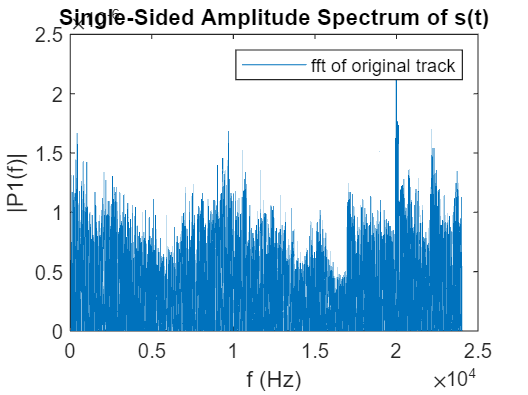

P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f,P1) 
title("Single-Sided Amplitude Spectrum of s(t)")
legend("fft of original track")
xlabel("f (Hz)")
ylabel("|P1(f)|")

% plot of fft of convoluted track
k = size(x) % size of convoluted track

k =       811831           1


T = 1/Fs;             % Sampling period       
L = k(1);             % Length of signal
t = (0:L-1)*T;    % Time vector
P4 = abs(x/L);
P3 = P4(1:L/2+1);

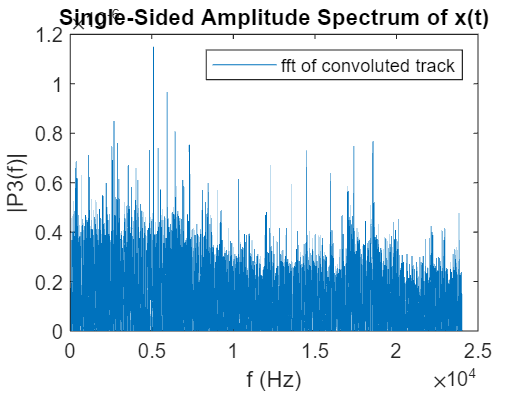

P3(2:end-1) = 2*P3(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f,P3) 
title("Single-Sided Amplitude Spectrum of x(t)")
legend("fft of convoluted track")
xlabel("f (Hz)")
ylabel("|P3(f)|")